clear; close; clc;
load("signal.mat");
X = signalB6;

L = length(X)

L = 1500

Fs = 1000

Fs = 1000

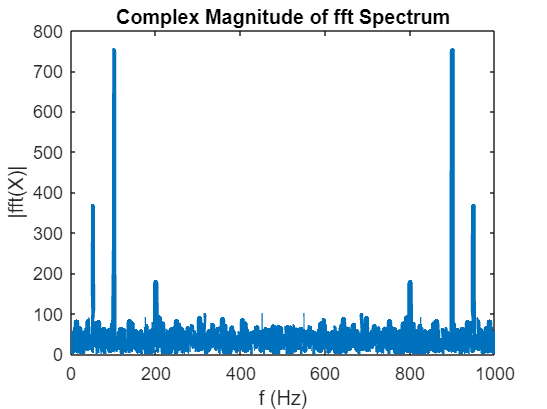


Y = fft(signalB6);
plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

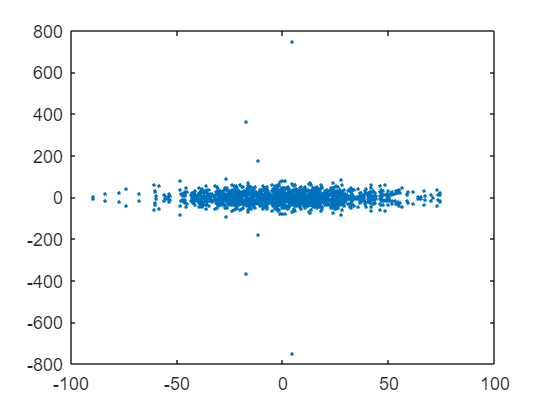


figure

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(Y,".");

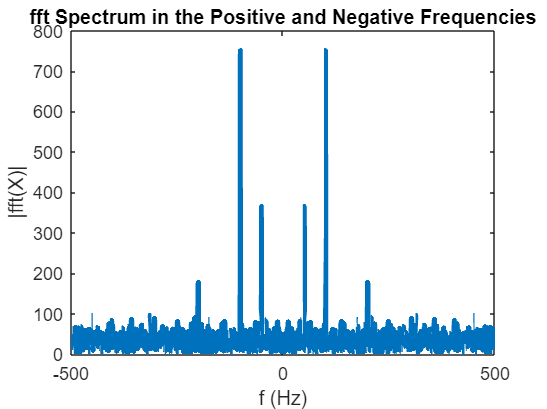


figure
plot(Fs/L*(-L/2:L/2-1),abs(fftshift(Y)),"LineWidth",3)
title("fft Spectrum in the Positive and Negative Frequencies")
xlabel("f (Hz)")
ylabel("|fft(X)|")